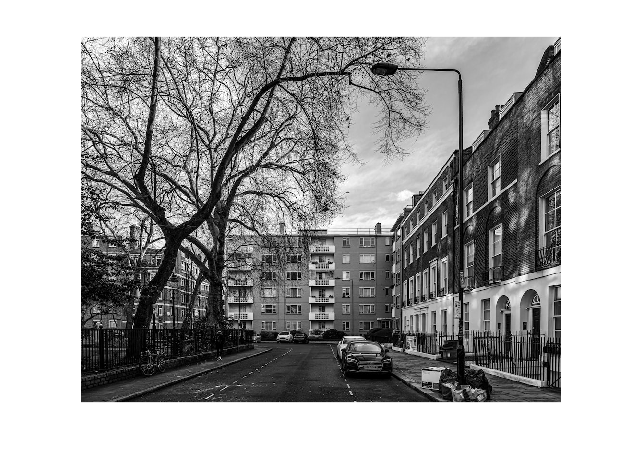

gray = imread('C:\Users\Harish\Downloads\ITC_img.png');
imshow(gray)

gray

gray = 761×1000 uint8 matrix
   196   242   253   238   235   252   228   219   249   225   176   240   248   240   203   227   232   237   241   246   230   227   228   238   228   143   171   255   233   220   247   241   245   211   208   250   223   227   241   244   199   193   231   237   217   232   230   200   175   186
   246   255   248   234   253   243   186   234   235   188   166   211   225   240   200   252   255   228   217   233   250   245   236   231   239   178   162   228   251   232   249   240   242   216   216   234   227   245   251   233   206   179   226   243   231   227   188   169   202   230
   234   245   242   239   245   234   198   238   247   249   255   244   215   225   169   165   244   236   203   179   235   236   221   213   250   242   195   206   254   216   229   246   239   186   217   234   242   252   244   244   252   165   201   238   222   186   141   165   235   226
   255   240   244   246   255   211   149   253   241   250   247  

array = reshape(gray,[761000,1]);
k=8;%message length
n=17;%code word length
f=double(de2bi(array,'left-msb'))

f =      1     1     0     0     0     1     0     0
     1     1     1     1     0     1     1     0
     1     1     1     0     1     0     1     0
     1     1     1     1     1     1     1     1
     1     1     1     1     0     0     1     1
     1     1     1     1     0     0     1     1
     1     1     1     1     0     1     0     0
     1     1     0     0     1     0     0     0
     0     1     0     1     1     1     1     1
     1     0     0     0     0     0     1     1


pol=cyclpoly(n,k)

pol =      1     0     0     1     1     1     1     0     0     1


parmat=cyclgen(n,pol)

parmat =      1     0     0     0     0     0     0     0     0     1     0     0     1     1     1     0     0
     0     1     0     0     0     0     0     0     0     0     1     0     0     1     1     1     0
     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     1     1
     0     0     0     1     0     0     0     0     0     1     0     0     0     1     1     1     1
     0     0     0     0     1     0     0     0     0     1     1     0     1     1     0     1     1
     0     0     0     0     0     1     0     0     0     1     1     1     1     0     0     0     1
     0     0     0     0     0     0     1     0     0     1     1     1     0     0     1     0     0
     0     0     0     0     0     0     0     1     0     0     1     1     1     0     0     1     0
     0     0     0     0     0     0     0     0     1     0     0     1     1     1     0     0     1


genmat=gen2par(parmat)

wt = 5

genmat =      1     0     0     1     1     1     1     0     0     1     0     0     0     0     0     0     0
     0     1     0     0     1     1     1     1     0     0     1     0     0     0     0     0     0
     0     0     1     0     0     1     1     1     1     0     0     1     0     0     0     0     0
     1     0     0     0     1     1     0     1     1     0     0     0     1     0     0     0     0
     1     1     0     1     1     0     0     0     1     0     0     0     0     1     0     0     0
     1     1     1     1     0     0     1     0     0     0     0     0     0     0     1     0     0
     0     1     1     1     1     0     0     1     0     0     0     0     0     0     0     1     0
     0     0     1     1     1     1     0     0     1     0     0     0     0     0     0     0     1


encData= encode(f,n,k,'linear/binary',genmat)

encData =      0     0     1     0     0     0     1     1     0     1     1     0     0     0     1     0     0
     1     1     1     1     0     0     0     0     0     1     1     1     1     0     1     1     0
     0     1     0     1     0     1     1     1     0     1     1     1     0     1     0     1     0
     0     0     0     1     0     1     0     0     0     1     1     1     1     1     1     1     1
     0     0     1     1     1     1     1     0     1     1     1     1     1     0     0     1     1
     0     0     1     1     1     1     1     0     1     1     1     1     1     0     0     1     1
     1     0     0     0     1     0     0     1     0     1     1     1     1     0     1     0     0
     0     0     0     0     1     0     0     1     1     1     1     0     0     1     0     0     0
     1     0     1     0     1     1     0     1     1     0     1     0     1     1     1     1     1
     1     1     0     1     1     0     1     1     1     1   

ndata1=bsc(encData,0.9)

ndata1 =      1     1     0     1     1     1     0     0     0     0     0     0     1     1     0     1     1
     1     1     0     0     1     1     1     1     0     0     0     0     0     1     0     1     1
     1     0     0     0     1     0     0     0     1     1     0     0     1     1     1     0     1
     1     1     1     0     1     0     1     1     1     0     1     0     0     0     1     0     1
     1     1     1     1     0     0     0     0     0     0     0     0     0     1     1     0     0
     1     1     0     0     1     1     0     1     0     0     0     1     0     1     1     0     0
     0     1     1     0     1     1     1     0     1     0     0     0     0     0     0     1     0
     1     1     1     1     0     1     1     0     0     0     0     1     1     0     1     1     1
     0     1     0     1     0     0     1     0     0     1     0     1     0     0     1     0     0
     0     0     0     0     0     1     0     0     0     0    

ndata2=bsc(ndata1,0.5)

ndata2 =      0     1     1     1     1     1     1     1     0     0     1     0     1     0     0     1     0
     1     1     1     1     0     1     1     1     0     1     1     0     0     1     0     0     0
     1     0     0     1     1     1     0     1     0     0     1     1     1     0     0     0     0
     1     1     1     0     1     0     1     0     1     1     0     0     0     0     0     0     1
     1     1     0     1     1     1     1     0     0     1     1     0     1     0     1     0     1
     1     1     1     1     0     1     0     0     1     0     1     1     0     0     1     1     1
     0     1     1     0     1     1     0     1     0     1     1     0     1     1     1     0     1
     1     1     0     1     0     0     1     1     0     1     1     1     0     1     1     0     1
     1     0     0     1     1     0     0     0     0     1     0     0     1     1     1     0     1
     1     0     0     1     0     1     1     1     0     0    

ndata3=bsc(ndata2,0.1)

ndata3 =      0     1     0     0     0     1     1     0     0     1     1     0     1     0     1     1     0
     1     1     1     1     0     1     1     1     0     1     1     0     0     1     0     0     0
     1     0     1     1     1     1     0     0     0     0     1     1     1     0     0     0     0
     1     1     1     0     1     0     1     0     0     0     0     0     0     1     0     0     1
     1     1     0     1     1     1     1     1     0     1     1     1     1     0     1     0     1
     1     1     1     1     0     1     0     0     1     0     1     1     0     0     0     1     1
     0     1     1     0     1     0     0     0     0     1     1     1     1     1     1     0     1
     1     0     0     0     0     0     1     0     0     1     1     1     0     1     1     0     1
     1     0     0     1     1     0     0     0     0     1     0     0     1     1     1     0     1
     1     0     1     1     0     1     0     1     0     0    

[decData,errc]=decode(ndata3,n,k,'linear/binary',genmat)   

Single-error patterns loaded in decoding table.  494 rows remaining.
2-error patterns loaded.  358 rows remaining.
3-error patterns loaded.  120 rows remaining.
4-error patterns loaded.  1 rows remaining.
5-error patterns loaded.  0 rows remaining.


decData =      1     1     0     1     0     1     1     0
     1     1     0     0     1     0     0     1
     0     1     1     1     0     0     1     0
     1     0     0     0     1     0     0     1
     1     1     1     1     1     0     0     1
     0     1     1     0     1     0     1     1
     1     1     1     1     1     1     0     1
     0     1     1     0     1     1     0     0
     1     0     0     0     1     1     0     1
     0     0     1     1     1     1     0     1


errc =      4
     4
     2
     3
     3
     2
     2
     4
     2
     3


s=mod(ndata3*transpose(parmat),2)

s =      1     0     0     1     0     0     0     1     1
     1     1     1     1     1     1     1     0     1
     0     1     0     1     1     0     0     1     0
     0     0     0     0     1     1     1     0     0
     0     1     1     0     1     0     1     0     1
     1     1     0     1     1     0     0     1     1
     0     0     0     0     0     1     0     1     0
     0     1     1     0     0     0     1     0     1
     1     0     0     1     1     1     0     1     1
     1     1     0     1     0     0     0     1     1


a=sum(s,2)

a =      4
     8
     4
     3
     5
     6
     2
     4
     6
     5


errd=761000-sum(a==0);

decD=bi2de(decData,'left-msb')

decD =    214
   201
   114
   137
   249
   107
   253
   108
   141
    61


img=uint8(reshape(decD,[761,1000]))

img = 761×1000 uint8 matrix
   214   227   170   180    73    52   232    16    74   217   206   133    98   100    61   207   165   174    87   166    26   135   240   204   207   141   137   163   252   219   116    40   136   219   146    50    47   252    16   213   221    53   245   218   105   204   186   135    57   164
   201    73   221   120     3   214   106    91   140   226    27   189   206   125    10   165    19   207    13   204   129    83    99   107    57    21   151   167    63   233   245    64   254    31   155    75    49   109   177   211   102   244   137    86   231   206    97     7   227   152
   114   127    37   246   101   177    95   196   218   153   222    57   172   186   142   214   107   134     9   134    17    64     7    35   223    60    19   249    32   189   188   153   230   132   244     3   132    13    29   118   219   115    94   228   251    61   148    18   186    75
   137    36   193   186    52   139    11    42    84   220    36   

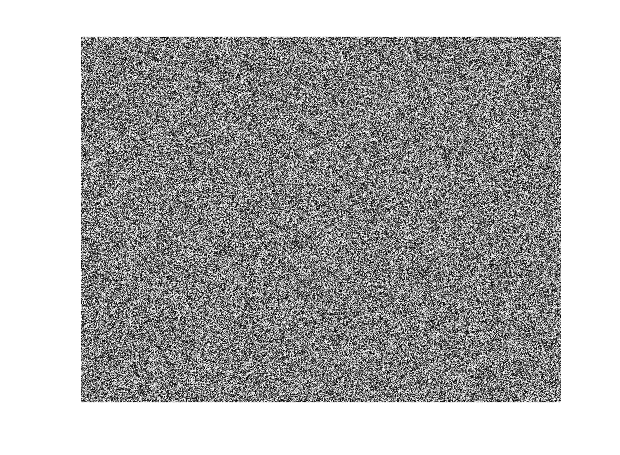

imshow(img,[0 256])

errc=sum(errc)%number of error corrected bits

errc = 2205234

errd=errd*8%number of error detected bits

errd = 6076040